# Analyzing Labeled Volumes

## Overview

When labeling a volume, the Medical Image Labeler App first creates a new Label Data volume the same size as the original volume and assigns all the voxels a value of 0. As labels are drawn in the app, the corresponding voxel values in the labeled volume are set equal to the label ID. 

The `groundTruthMedical` object created by the labeling session ties all the session data together. It contains the following information:

- `DataSource`: The path to the original medical images for each volume

- `LabelData`: The path to the corresponding labeled volumes

- `LabelDefinitions`: A table containing the name, color, and ID of each label

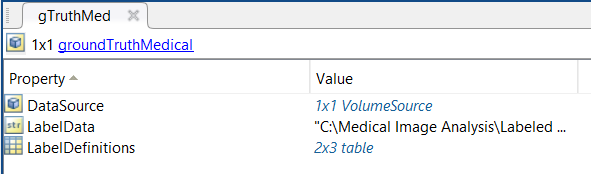

## Inspect `gTruthMed` Object

The label session folder and `grouthTruthMed.mat` file are created at the same time. Initially, the property values are empty. They are updated as the corresponding data is added to the session. 

The code in the next section displays the property values of a groundTruthMedical object you specify. If you have not yet done so, follow these steps to create a `grouthTruthMed.mat` file: 

- Start a volume session in the Medical Image Labeler App

- Import one of the MRI data sets provided in the course files

- Define a label

- Add a label to your volume

Once you have completed these step, uncomment and run the code in the following section.

Load the `groundTruthMed.mat` file from your labeling session folder.

% sessionFolder = "";
% load(fullfile(sessionFolder,"groundTruthMed.mat"))

This will load a ground truth medical object named `gTruthMed` into the Workspace. Let's look at the information it contains.

`DataSource`

This field will contain a `Source` for each volume imported into the session. The code below displays the full path of the images in the first volume.

% gTruthMed.DataSource.Source{1}

`LabelData`

When labels are added to a volume in the app, a new labeled volume is created. The code below displays the full path to this labeled volume.

% gTruthMed.LabelData(1)

`LabelDefinitions`

Labels definitions must be created in the Medical Image Labeler App in order to label volumes. The `LabelDefinitions` table maps each label name to its corresponding ID. 

% gTruthMed.LabelDefinitions

## Inspect Labeled Volume

We used the Medical Image Labeler App to label the left and right hemispheres in the T1-weighted 3 Tesla MRI data. Let's inspect the results using the labeled volume included in the course files.

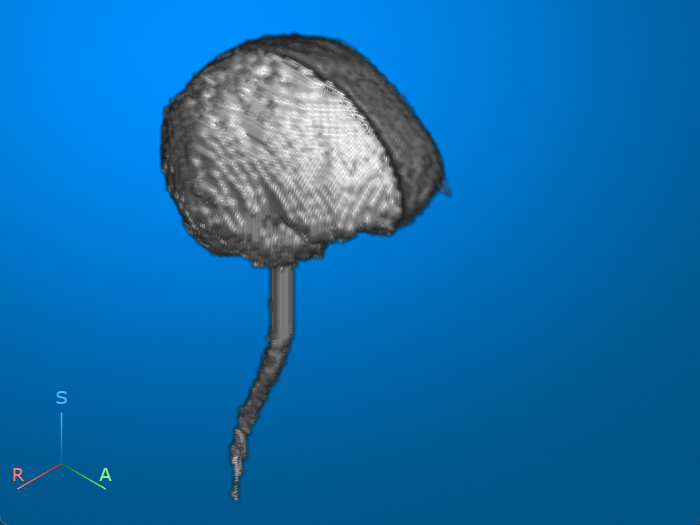

It can be loaded using `medicalVolume` just like 3D medical images.

**Note: **If this code returns an error, [add the course Data folder to your MATLAB Path](https://www.mathworks.com/help/matlab/matlab_env/add-remove-or-reorder-folders-on-the-search-path.html#mw_dd8cd98e-9ceb-4441-b2e3-b10401cf93c8).

segVol = medicalVolume('T1_3T_2018.nii')

Most properties, including voxel spacing, number of slices, and plane mapping, are the same as the T1_3T_2018 data you have worked with previously. 

The important difference is the values stored in the labeled volume's Voxels property. Use the [`unique` function](https://www.mathworks.com/help/matlab/ref/double.unique.html) to display the unique values. 

unique(segVol.Voxels)

These values should look familiar. These are the label IDs. The corresponding label names are found in the `LabelDefinitions` table. Background, which is not included in the table, is assigned a label ID of 0 by the Medical Image Labeler App.

**Note:** Each voxel can only be assigned one label ID.

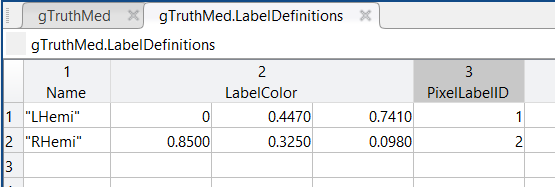

## View Labeled Volume

Explore the slices of the labeled volume using the `orthosliceviewer`. 

orthosliceViewer(segVol)

Use the Data Tip tool in the axes toolbar to confirm that voxel values are the label IDs.

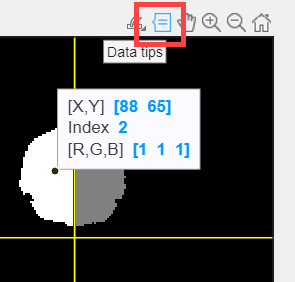

## Measure Region Properties

Labels often correspond to specific structures in your volume. Your analysis may require reporting various statistics for each label.

Use [`regionprops3`](https://www.mathworks.com/help/images/ref/regionprops3.html) to measure properties for each labeled region.

The following code computes the volume of each label in the segmented volume.

segProps = regionprops3(segVol.Voxels,"Volume")

Because the input is `segVol.Voxels`, the output is in voxels, meaning the number of voxels with the corresponding ID.

Multiply the result by the real-world voxel-spacing to convert the value to $mm^3$.

segProps.VolumeMM3 = segProps.Volume*prod(segVol.VoxelSpacing)

## Measure Labeled Voxel Values

With the volume segmented into various regions of interest, it is also possible to make measurements of voxel intensity values by region. 

Use [`regionprops3`](https://www.mathworks.com/help/images/ref/regionprops3.html) again, with the first input being the labeled voxel values, the second being the corresponding intensity voxel values, and the third specifying the property to measure.

**Note: **If this code returns an error, [add the course Data folder to your MATLAB Path](https://www.mathworks.com/help/matlab/matlab_env/add-remove-or-reorder-folders-on-the-search-path.html#mw_dd8cd98e-9ceb-4441-b2e3-b10401cf93c8).

% Select the T1_3T_2018 folder in the course Data folder
mriFolder = "";
medVol = medicalVolume(mriFolder);
volProps = regionprops3(segVol.Voxels,medVol.Voxels,"MeanIntensity")

The output is in the same units as voxel intensity.

## Hounsfield Units

The intensity values of CT images may be calibrated to correspond to different tissue density levels. This calibrated intensity is reported in Hounsfield Units.

The intensity values of medicalImage and medicalVolume objects are automatically rescaled to Hounsfield Units if the associated metadata properties are present.

*Copyright 2024 The MathWorks, Inc.*